close all
clc
disp('Elias Assaf 315284729 - Jameel Nassar 206985152')

## Section 1:

if we look closely at the equation for the fourier transform, we notice that we sum over all m and all n, we can change the order of the summation a little, and give it a matrix form instead of doing it in foor loops, which would take O(M*N) calculations for each cell, and there is M*N cells.

we derive the matrix equations for the fft:

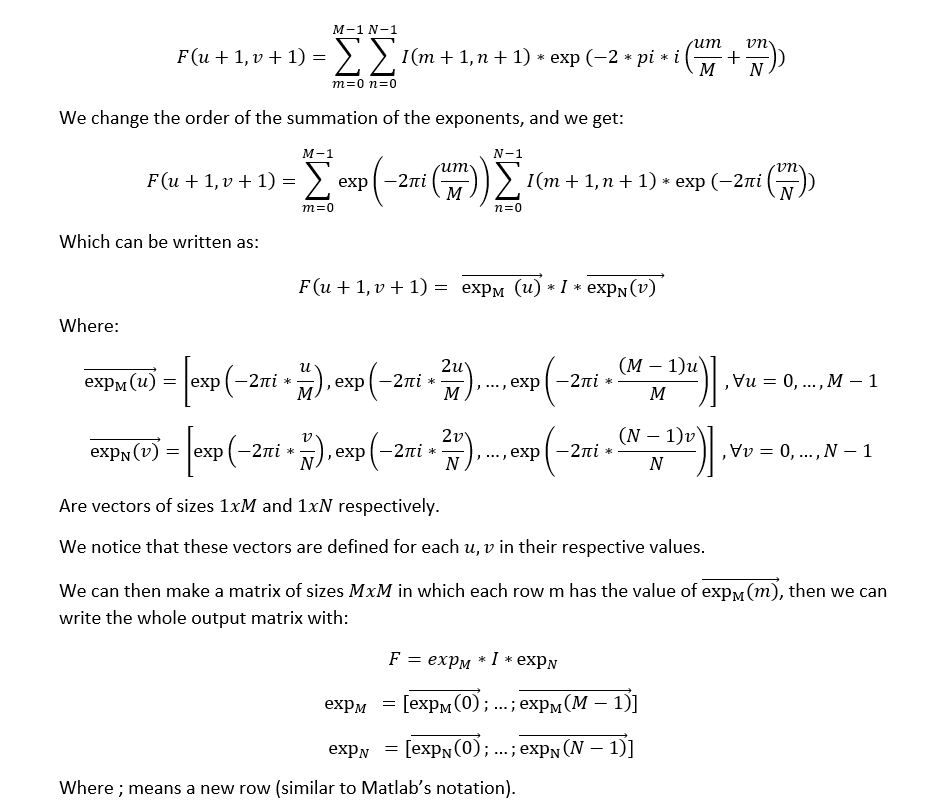

similarly for ifft.

the fftshift is simply dividing the matrix into 4 quadrants and swapping quadrant 1 and 4, 2 and 3.

note that for this to work N,M need to be even numbers.

## Section 1.1


beatles = imread("beatles.png");
beatles_norm = double(rgb2gray(beatles))/255;
beatles_fft2 = dip_fft2(beatles_norm);
beatles_fft2_matlab = fft2(beatles_norm);
figure;sgtitle("fft2 of beatles")
subplot(2,2,1);imagesc(log10(abs(dip_fftshift(beatles_fft2))));title("our version Amplitude");colorbar;
subplot(2,2,2);imagesc(angle(dip_fftshift(beatles_fft2)));title("phase");colorbar;
subplot(2,2,3);imagesc(log10(abs(dip_fftshift(beatles_fft2_matlab))));title("matlab version Amplitude");colorbar;
subplot(2,2,4);imagesc(angle(dip_fftshift(beatles_fft2_matlab)));title("phase");colorbar;


beatles_ifft2 = dip_ifft2(beatles_fft2);
beatles_ifft2_matlab = ifft2(beatles_fft2_matlab);
figure;sgtitle("ifft2 of beatles")
subplot(2,2,1);imshow(beatles_norm);title("original image");
subplot(2,2,2);imshow(real(beatles_ifft2));title("our ifft");
subplot(2,2,4);imshow(real(beatles_ifft2_matlab));title("matlab ifft");

in the next section we want to free willy.

## Section 1.2.1

load("freewilly.mat");
imprisoned_willy = freewilly;
figure;imshow(imprisoned_willy);title("imprisoned willy");

we take a mental exercise where we imagine a sin function on the x axis with the parameters:

sin(2*pi*f_x/N * x), x=0,...,N-1

for f_x=1 we only get 1, for f_x=2 we get 2 cycles and so on...

we count the number of cycles of the black and white bars in the picture and notice the very nice fact that they are a nice even integer number of value 10, which is the f_x we are looking for.

[M,N] = size(imprisoned_willy);
[X_grid, Y_grid] = meshgrid(0:N-1, 0:M-1);
f_x = 10;
prison = 0.5 * sin(2*pi*f_x/N * X_grid);
figure;imshow(prison);title("prison")
%freed_willy = imprisoned_willy - prison;
%figure;imshow(freed_willy);title("freed willy by -");

after building the prison ourselves and using fft on it, we expect to have a "lambda" function on the frequency domain where the peaks exist on ± f_x.

and since we have no signal in the y axis (or DC signal with value 0) we expect its fft to be 0 at all the frequencies.

prison_fft = fft2(prison);
figure;imshow(abs(dip_fftshift(prison_fft)));title("prison fft2")

to free william (how he likes to be called after being in prison for so long) we go to the fourier domain and zero out the peaks of the prison bars, i.e at ± f_x.

because we dont want to waste computation time, we don't use fftshift first, rather we go to y=1 and to the points ***x_1=1+f_x,*** ***x_2 = 1+end-f_x*** and zero them out, then we use the ifft to back to space domain and were done.

Free_Willy(imprisoned_willy);

yay

## Section 1.2.2



square_1 = zeros(128, 128);
[square_1_X, square_1_y] = meshgrid(44:83, 44:83);
idx_1 = sub2ind(size(square_1), square_1_X, square_1_y);
square_1(idx_1) = 1;
square_1_fft = fft2(square_1);
figure;
subplot(1,2,1);imshow(square_1);title("square 1")
subplot(1,2,2);imshow(abs(dip_fftshift(square_1_fft)));title("square1 fft2")


square_2 = zeros(128, 128);
[square_2_X, square_2_y] = meshgrid(64:103, 64:103);
idx_2 = sub2ind(size(square_2), square_2_X, square_2_y);
square_2(idx_2) = 1;
square_2_fft = fft2(square_2);
figure;
subplot(1,2,1);imshow(square_2);title("square 2");
subplot(1,2,2);imshow(abs(dip_fftshift(square_2_fft)));title("square 2 fft2");
figure;
subplot(1,2,1);imshow(abs(dip_fftshift(square_1_fft)));title("square1 fft2")
subplot(1,2,2);imshow(abs(dip_fftshift(square_2_fft)));title("square2 fft2");
sum(square_1_fft == square_2_fft, 'all')

we notice that most of the values are not the same, that is because when we move the square we change its phase, so they get multipled by sin/cos of the phase difference.

we base our answer on the fact that shifting in time equals multiplying by an exponent of the shifter value in frequency domain.

similarly in 2d transform, so the amplitude of images should be equal.

We can get a better comparison if we  calculte the log of the 2d-fft of each image and devide by 10.

figure;
subplot(2,2,1);imshow(log(abs(dip_fftshift(square_1_fft)))*10);title("log(fft2(square1))/10")
subplot(2,2,2);imshow(log(abs(dip_fftshift(square_2_fft)))*10);title("log(fft2(square2))/10");
subplot(2,2,3);imshow(angle(dip_fftshift(square_1_fft)));title("square1 fft2 phase");
subplot(2,2,4);imshow(angle(dip_fftshift(square_2_fft)));title("square2 fft2 phase");

As we can see in figures above the amplitudes are equal but the phases are not, which confirm our mathematical theory.

square_3 = zeros(128, 128);
[square_3_X, square_3_y] = meshgrid(24:103, 54:73);
idx_3 = sub2ind(size(square_3), square_3_X, square_3_y);
square_3(idx_3) = 1;
square_3_fft = fft2(square_3);
figure;
subplot(1,2,1);imshow(square_3);title("square 3");
subplot(1,2,2);imshow(abs(dip_fftshift(square_3_fft)));title("square 3 fft2");
figure;
subplot(1,3,1);imshow(abs(dip_fftshift(square_1_fft)));title("square1 fft2")
subplot(1,3,2);imshow(abs(dip_fftshift(square_2_fft)));title("square2 fft2");
subplot(1,3,3);imshow(abs(dip_fftshift(square_3_fft)));title("square 3 fft2");

we remember the time scaling property of the fourier transform, in the x axis a=2, so in the frequency domain we can see the x axis expanded, i.e the little squares became bigger.

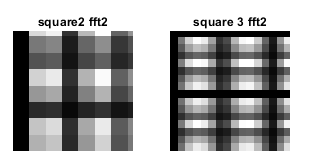

bottom left corner for example.

similar thing on the y axis but we have a=1/2, so in the frequency domain the y axis shrunk

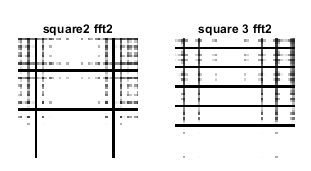

upper middle section for example.

similar thing on the y axis but we have a=1/2, so in the frequency domain the y axis shrunk

figure;
subplot(1,3,1);imshow(log(abs(dip_fftshift(square_1_fft)))/10);title("log(fft2(square1))/10")
subplot(1,3,2);imshow(log(abs(dip_fftshift(square_2_fft)))/10);title("log(fft2(square2))/10");
subplot(1,3,3);imshow(log(abs(dip_fftshift(square_3_fft)))/10);title("log(fft2(square3))/10");

Like we did previously if we look at the log of the amplitude we can the effects more clearly in the frequency domain, and if we compare the first and third squares we can see that the y axis shrunk and the x axis expanded.

we can represent the 80x20 square by the 2 vectors

[1;...;1] * [1,...,1], the first begin of size 80x1 and the second of size 1x20.

we pad with zeros to get the correct length of 128x128

vec_80_1 = [zeros(24,1); ones(80,1); zeros(24,1)];
vec_1_20 = [zeros(1,54), ones(1,20), zeros(1,54)];
square_80_20 = vec_80_1 * vec_1_20;
figure;sgtitle("the 2 vectors");
subplot(1,2,1);imshow(vec_80_1);title('80x1 padded to 128x1');
subplot(1,2,2);imshow(vec_1_20);title('1x20 padded to 1x128');
figure;imshow(square_80_20);title("80x20 square by multiplying vectors");

as we saw in the first section we got:

where I is our image, we can simply write it in its vector form and we get:

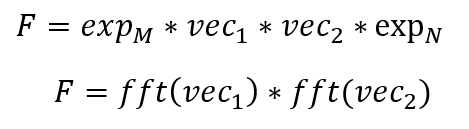

we write our function accordingly.

square_3_sep_fft = sep_fft2(vec_80_1, vec_1_20);
figure;
subplot(1,2,1);imshow(abs(dip_fftshift(square_3_fft)));title("square3 fft2")
subplot(1,2,2);imshow(abs(dip_fftshift(square_3_sep_fft)));title("square3 fft2 by separating");

as we can see they are identical !!!!!.

## Section 2

beatles = imread("beatles.png");
beatles_norm = double(rgb2gray(beatles))/255;
beatles_dct2 = dct2(beatles_norm);
[M_beatles, N_beatles] = size(beatles_norm);
figure;imagesc(log(abs(beatles_dct2)));colormap(jet(64));colorbar;title('dct of beatles image')

to remove half of the values randomly, we take a random permutation of the number of elements in the dct domain, take half of them, and zeros out those indexes in the dct matrix.

half_ones_rand = randperm(numel(beatles_dct2));
half_ones_rand = half_ones_rand(1:end/2);
beatles_dct2_half_rand = beatles_dct2;
beatles_dct2_half_rand(half_ones_rand) = 0;
beatles_idct2_half_rand = idct2(beatles_dct2_half_rand);
figure;sgtitle("half values removed randomly from dct domain");
subplot(1,2,1);imshow(beatles_norm);title("original image");
subplot(1,2,2);imshow(beatles_idct2_half_rand);title("50% values removed randomly");
perc = sum(beatles_dct2_half_rand == 0, 'all') / numel(beatles_dct2)

for the next section, we need to zero out the half lower absolute values of the dct, for that we remember the definition of median, the value which separates the higher half from the lower half of the data, which means that we can zero out all the values smaller than the median value .

notice that here we only deal in absolutes.

beatles_dct2_half_lowest = beatles_dct2;
beatles_dct2_abs_median = median(abs(beatles_dct2_half_lowest), 'all')
beatles_dct2_half_lowest(beatles_dct2_half_lowest < beatles_dct2_abs_median & beatles_dct2_half_lowest > -beatles_dct2_abs_median) = 0;
beatles_idct2_half_lowest = idct2(beatles_dct2_half_lowest);
figure;sgtitle("half absolute lowest values removed from dct domain (values lower than the median)");
subplot(1,2,1);imshow(beatles_norm);title("original image")
subplot(1,2,2);imshow(beatles_idct2_half_lowest);title("50% lowest values removed")

for the next section we test which some values of a where we remove values from the dct domain which thier absolute value is smaller than a.


figure;sgtitle("values from (-a,a) removed from dct domain");
subplot(3,2,1);imshow(beatles_norm);title('original image');
i=2;
for a = [0.02 0.05 0.07 0.09 0.15]
    beatles_dct2_no_a = beatles_dct2;
    beatles_dct2_no_a(beatles_dct2_no_a < a & beatles_dct2_no_a > -a) = 0;
    beatles_idct2_no_a = idct2(beatles_dct2_no_a);
    perc = sum(beatles_dct2_no_a == 0, 'all') / numel(beatles_dct2);
    subplot(3,2,i);imshow(beatles_idct2_no_a);title(['a = ' num2str(a) ', percentage = ' num2str(perc)])
    i = i+1;
end

we choose a=0.05 to be the best value, it removes 60% of the values, and gives a good reconstruction of the photo without too much noise.

as we saw in class, most of the information exists in the higher values of the dct domain, so removing the about 50-70% of values still gives a reconstruction which we can understand and sometimes not even notice that it was compressed.

but for example when we randomly removed half of the values, we removed some of the important values and we lost most of the information of the image.

## Section 3


beetle = imread("beetle.jpg");
beetle_norm = double(rgb2gray(beetle))/255;
n=5;
[c_beetle,s_beetle]=wavedec2(beetle_norm,n,'haar');


In this section we chose 5 decomposition levels.

The chart describes the basic decomposition step for the image:

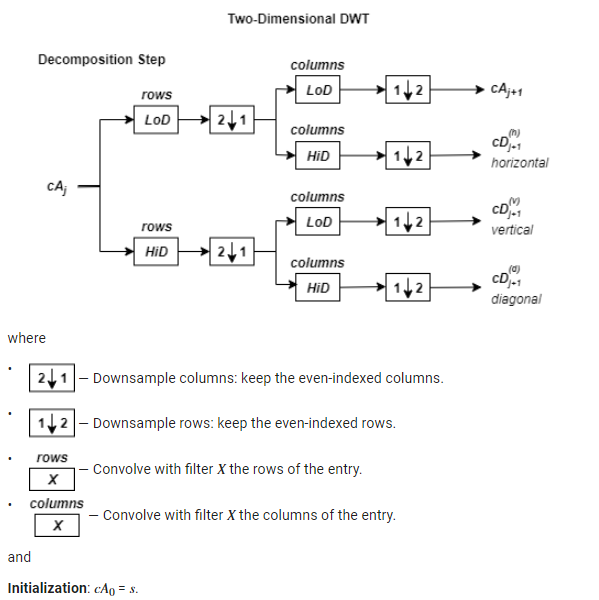

 `LoD` is the lowpass decomposition filter, and `HiD` is the highpass decomposition filter.

So, for *J* = 2, the two-dimensional wavelet tree has the form

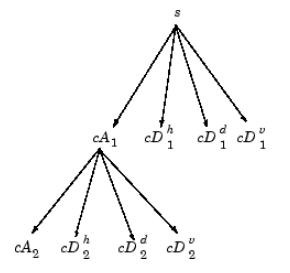

As we can see in the graph with each level increase we lose decrease the x and y pixel density by half which means we get quarter resolution of the original image, which also means that we lose some detail, we can can confirm this if we look at the x and y axis sizes of the different decomposition levels

each detail coefficients is shows the changes in pixels of sertain axis according to the chosen filter in the decomposition, and we can see that in the fiures below.

- *A* contains the approximation coefficients.

- *H* contains the horizontal detail coefficients.

- *V* contains the vertical detail coefficients.

- *D* contains the diagonal detail coefficients.

for i = 1:n
[h_beetle,v_beetle,detail_beetle] = detcoef2('all',c_beetle,s_beetle,i);
cfs2 = appcoef2(c_beetle,s_beetle,'haar',i);
V_img = wcodemat(v_beetle,255,'mat',i);
H_img = wcodemat(h_beetle,255,'mat',i);
D_img = wcodemat(detail_beetle,255,'mat',i);
A_img = wcodemat(cfs2,255,'mat',i);
figure;colormap('gray');
subplot(2,2,1);imagesc(A_img);title(['Approximation Coef. of Level '  int2str(i)]);
subplot(2,2,2);imagesc(H_img);title(['Horizontal Detail Coef. of Level '  int2str(i)]);
subplot(2,2,3);imagesc(V_img);title(['Vertical Detail Coef. of Level '  int2str(i)]);
subplot(2,2,4);imagesc(D_img);title(['Diagonal Detail Coef. of Level ' int2str(i)]);
end



## functions

function [img_fft2] = dip_fft2(I)
    [M,N] = size(I);
    M_vec = (0:M-1);
    N_vec = (0:N-1);
    M_mat = exp(-2*pi*1i * (M_vec.' * M_vec)/M);
    N_mat = exp(-2*pi*1i * (N_vec.' * N_vec)/N);
    img_fft2 = M_mat * I * N_mat;
end

function [img_ifft2] = dip_ifft2(F)
    [M,N] = size(F);
    M_vec = (0:M-1);
    N_vec = (0:N-1);
    M_mat = exp(2*pi*1i * M_vec.' * M_vec/M);
    N_mat = exp(2*pi*1i * N_vec.' * N_vec/N);
    img_ifft2 = M_mat * F * N_mat;
    img_ifft2 = img_ifft2/(M*N);
end

function [shifted_fft2] = dip_fftshift(F)
    [M,N] = size(F);
    quad_1 = F(1:M/2,1:N/2);
    quad_2 = F(M/2+1:end, 1:N/2);
    quad_3 = F(M/2+1:end, N/2+1:end);
    quad_4 = F(1:M/2, N/2+1:end);
    shifted_fft2 = [quad_3 quad_2; quad_4 quad_1];
end

function [freed_willy] = Free_Willy(Willy)
    freed_willy = fft2(Willy);
    freed_willy(1, 1+10) = 0;
    freed_willy(1, 1+end-10) = 0;
    freed_willy = real(ifft2(freed_willy));
    figure;imshow(freed_willy);title("freed willy");
end

function [img_fft2] = sep_fft2(v1, v2)
    img_fft2 = fft(v1) * fft(v2);
end